intv = 500;
x = -1:1/intv:1; y = x; n = length(x);
c = ones(n,1)/n;
r = pdf('Normal',y,0,1)'; r = r/sum(r);
X0 = r*c';
C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = (y(i)-x(j))^2;
    end
end


figure
subplot(2,1,1);
plot(x,r);
title('Standard normal distr. histogram over [-1,1]')
subplot(2,1,2);
plot(x,c);
title('Uniform distr. histogram over [-1,1]')

## Optimal solution

f = reshape(C,[n^2,1]);
x_vec = reshape(X0,[n^2,1]);
A = zeros(2*n,n^2);
for i = 1:n
    A(1:n,(i-1)*n+1:i*n) = eye(n);
    A(n+i,(i-1)*n+1:i*n) = ones(1,n);
end
A = sparse(A);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Vanilla Random Block Coordinate Descent

[fval_rbcd,time_rbcd,feas_rbcd,card_rbcd,X1]=RBCD0(r,c,n,X0,f_opt,C,10000,5000,0);

iter = 1000, accuracy = 0.0084617
iter = 2000, accuracy = 0.0054916
iter = 3000, accuracy = 0.0044869
iter = 4000, accuracy = 0.0039587
iter = 5000, accuracy = 0.0036281
number of successful iterations =4476


## RBCD-Diagonal Band

[fval_rbcddb,time_rbcddb,feas_rbcddb,X1,card_rbcddb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,1,0); 

iter = 1000, accuracy = 0.013146
iter = 2000, accuracy = 0.0057895
iter = 3000, accuracy = 0.0035854
iter = 4000, accuracy = 0.0025783
iter = 5000, accuracy = 0.0019913
number of successful iterations =4835


## RBCD-Submatrix and Diagonal Band

[fval_rbcdsdb,time_rbcdsdb,feas_rbcdsdb,X1,card_rbcdsdb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,0.1,0);

iter = 1000, accuracy = 0.00018901
iter = 2000, accuracy = 3.2533e-05
iter = 3000, accuracy = 1.6314e-05
iter = 4000, accuracy = 1.0421e-05
iter = 5000, accuracy = 7.3298e-06
number of successful iterations =4999


## Accelerated RBCD

[fval_arbcd,time_arbcd,feas_arbcd,X1,card_arbcd]=ARBCD(r,c,n,X0,f_opt,C,100,5000,0);

iter = 1000, accuracy = 0.00011269
iter = 2000, accuracy = 7.3498e-06
iter = 3000, accuracy = 5.3182e-06
iter = 4000, accuracy = 4.0563e-06
iter = 5000, accuracy = 3.2796e-06
number of successful iterations =4991


## Plot

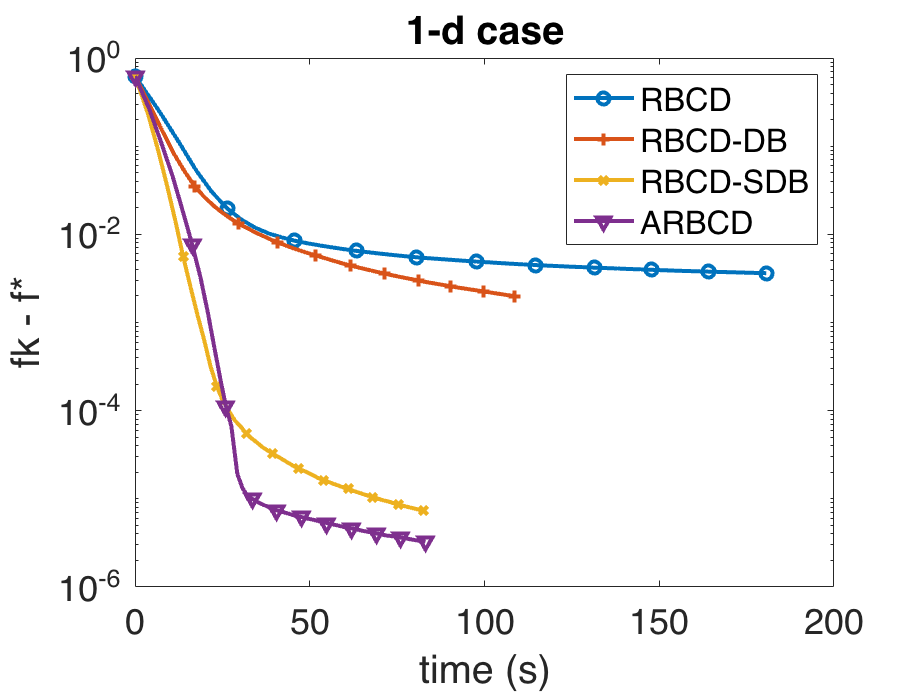

figure
semilogy(time_rbcd,fval_rbcd,'-o','MarkerIndices',1:5:length(fval_rbcd),'LineWidth',2)
hold on
semilogy(time_rbcddb,fval_rbcddb,'-+','MarkerIndices',1:5:length(fval_rbcddb),'LineWidth',2)
hold on
semilogy(time_rbcdsdb,fval_rbcdsdb,'-x','MarkerIndices',1:5:length(fval_rbcdsdb),'LineWidth',2)
hold on
semilogy(time_arbcd,fval_arbcd,'-v','MarkerIndices',1:5:length(fval_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('1-d case')
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',18)

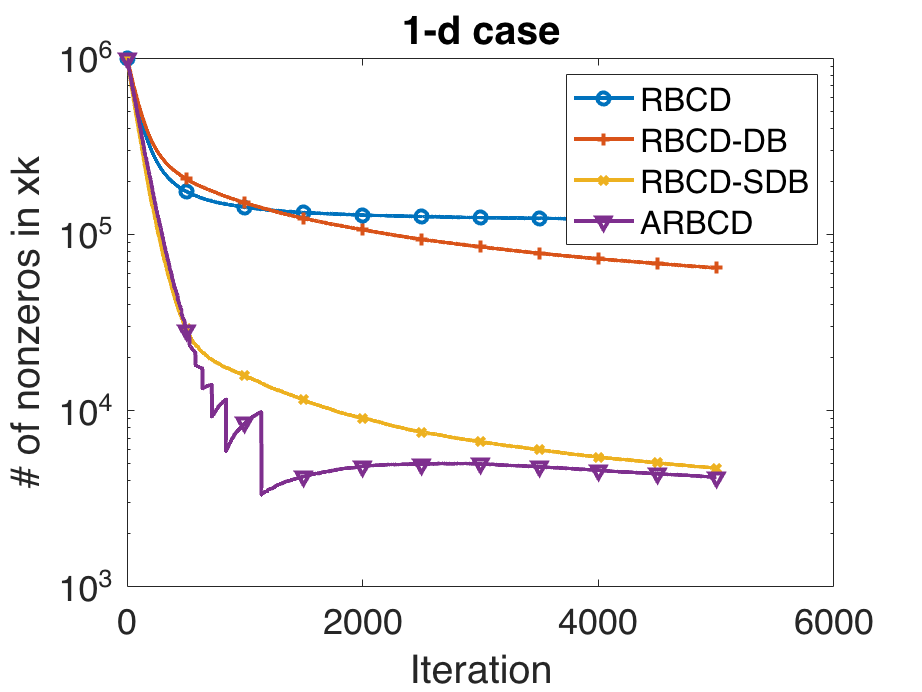

figure
semilogy(card_rbcd,'-o','MarkerIndices',1:500:length(card_rbcd),'LineWidth',2)
hold on
semilogy(card_rbcddb,'-+','MarkerIndices',1:500:length(card_rbcddb),'LineWidth',2)
hold on
semilogy(card_rbcdsdb,'-x','MarkerIndices',1:500:length(card_rbcdsdb),'LineWidth',2)
hold on
semilogy(card_arbcd,'-v','MarkerIndices',1:500:length(card_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('1-d case')
xlabel('Iteration')
ylabel('# of nonzeros in xk')
set(gca,'FontSize',18)